%Q22
v = linspace(0,1200);
k = 1.38e-23;
m = 5.3e-26;
T = [80;300];
T(1), T(2)

ans = 80

ans = 300

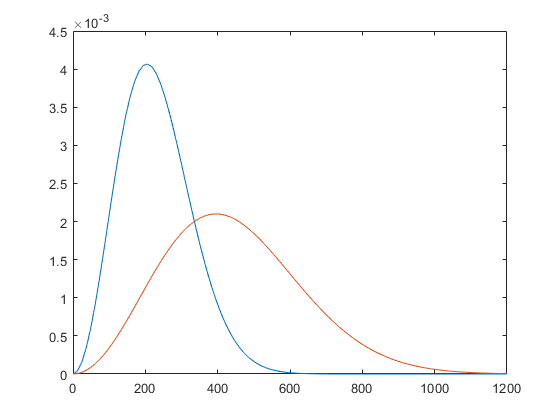

t1 = (m/(2*pi*k*T(1)))^1.5;
t2 = (-m*v.^2)/(2*k*T(1));

t3 = (m/(2*pi*k*T(2)))^1.5;
t4 = (-m*v.^2)/(2*k*T(2));

N_v  = (4*pi*t1)*(v.^2).*exp(t2);
N_v2 = (4*pi*t3)*(v.^2).*exp(t4);

plot(v, N_v) 
hold on
plot(v, N_v2) 
hold off

%Ideal gas a = 1, b = 0
T = 300;
R = 0.08206;
% PV = nRT
% n = 1, PV/RT = n = 1 

% nitrogen a, b at 300K (n = 1)
n = 1;
a = 1.39; b = 0.0391;
V = 0.08:0.02:6;

%PV = nRT/(V-nb) - n^2a/V^2
P = (n*R*T)./(V-n*b) - (((n^2)*a)./V.^2)

P =   384.7196  265.2365  207.7738  173.0658  149.3260  131.8184  118.2519  107.3672   98.4066   90.8820   84.4622   78.9135   74.0655   69.7903   65.9902   62.5887   59.5253   56.7513   54.2271   51.9200   49.8028   47.8529   46.0510   44.3807   42.8281   41.3810   40.0291   38.7630   37.5750   36.4579   35.4056   34.4125   33.4738   32.5851   31.7425   30.9425   30.1819   29.4579   28.7680   28.1096   27.4808   26.8796   26.3042   25.7529   25.2243   24.7170   24.2297   23.7613   23.3107   22.8769


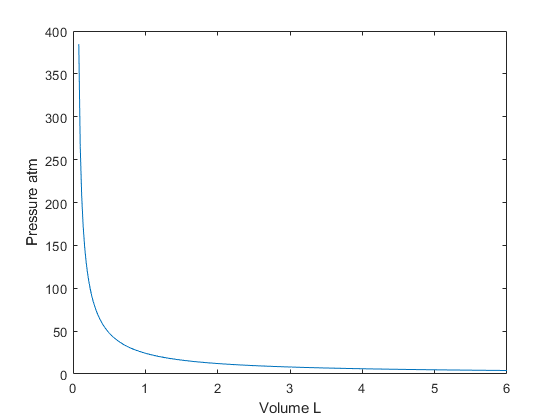

plot(V,P)
xlabel('Volume L')
ylabel('Pressure atm')

PV_RT = (P.*V)/(R*T)

PV_RT =     1.2502    1.0774    1.0128    0.9842    0.9705    0.9638    0.9607    0.9595    0.9594    0.9598    0.9607    0.9617    0.9627    0.9639    0.9650    0.9661    0.9672    0.9682    0.9692    0.9702    0.9711    0.9719    0.9727    0.9735    0.9742    0.9749    0.9756    0.9762    0.9768    0.9774    0.9780    0.9785    0.9790    0.9795    0.9799    0.9804    0.9808    0.9812    0.9816    0.9820    0.9823    0.9827    0.9830    0.9833    0.9836    0.9839    0.9842    0.9845    0.9848    0.9850


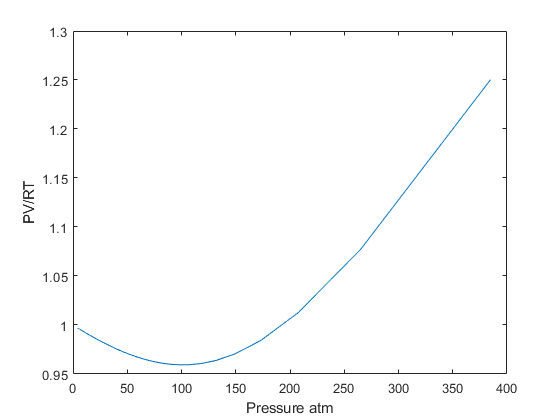

plot(P, PV_RT)
xlabel('Pressure atm')
ylabel('PV/RT')

%Q32
R = 8.314;
T = [100 200 300 400];
n = 1;
V = linspace(1,10);

P = (n*R.*T)./V'

P = 	1.0e+03 *

    0.8314    1.6628    2.4942    3.3256
    0.7621    1.5242    2.2864    3.0485
    0.7035    1.4070    2.1105    2.8140
    0.6532    1.3065    1.9597    2.6130
    0.6097    1.2194    1.8291    2.4388
    0.5716    1.1432    1.7148    2.2864
    0.5380    1.0759    1.6139    2.1519
    0.5081    1.0162    1.5242    2.0323
    0.4813    0.9627    1.4440    1.9253
    0.4573    0.9145    1.3718    1.8291


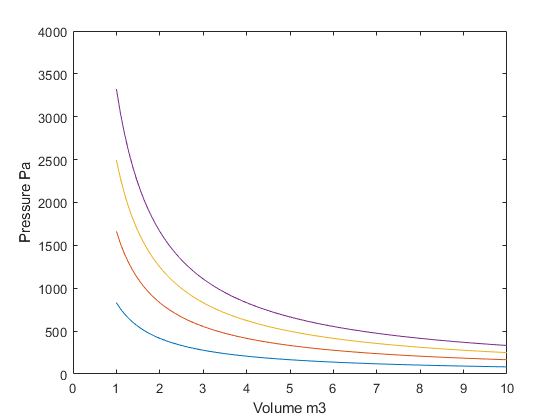

plot(V, P)
xlabel('Volume m3')
ylabel('Pressure Pa')
axis([0,10,0,4000]);